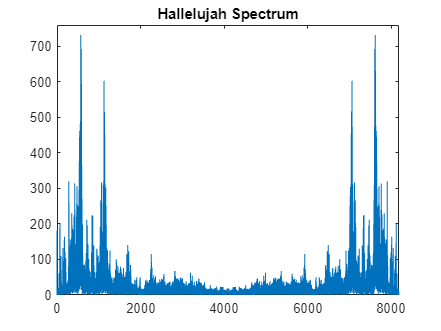

% Starting point for PV processing
load handel.mat  
x = y'; 
x = x(1:65536);

% Calculate FFT and freq axis 
Y = fft(y); 
freqInc = Fs / length(Y); 
freqAxis = 0:freqInc:(Fs - freqInc); 

% Plot spectrum
plot(freqAxis, abs(Y)) 
title("Hallelujah Spectrum")
axis([0 8191 0 760]) 


% Set scaling constants anHop, synthHop 
winSize = 1024;
anHop = 256; 
synthHop = 270;

% Call function to take STFTs of sequence PVAnalysis() 
[Moduli, Phase] = PVAnalysis(x, winSize, anHop);  

Window Size: 1024
Hop Size: 256
# Windows: 251

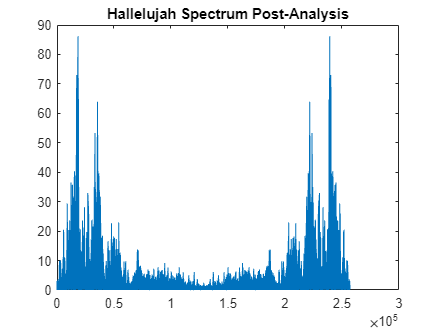

temp = reshape(Moduli, 1, []);
plot(fftshift(temp))  
title("Hallelujah Spectrum Post-Analysis") 

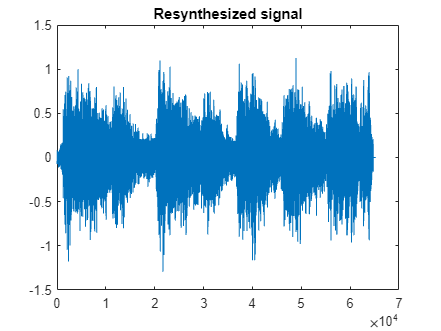


% Reconstructed signal
y = PVSynthesis(Moduli, Phase, anHop, synthHop);  
% Pitch-Shift  
% TODO: Resampling could be moved to freq domain
y = resample(y, anHop, synthHop);
plot(y) 
title("Resynthesized signal")

soundsc(y, Fs)